# Efficient Code Writing 

## Code Debugger and Analyzer

#### Syntax error

MATLAB Code Analyzer identifies syntax errors in a script or function *before*  executing code.

% a = 2*(3-1

**red** (errors) and **orange** (warnings) indicator

Red

- File contains syntax errors or other significant issues.

- There is a potential for unexpected results or poor code performance.

- a small red icon in the top right hand corner of the Live Editor & corresponding prompts when mousing over the red bar

Orange: 

- File contains warnings or opportunities for improvement, but no errors.

- suppress the warnings:  `warning(``'off'``,``'all'``)`

#### Runtime error

**MATLAB debugger**

Workflow of debugging

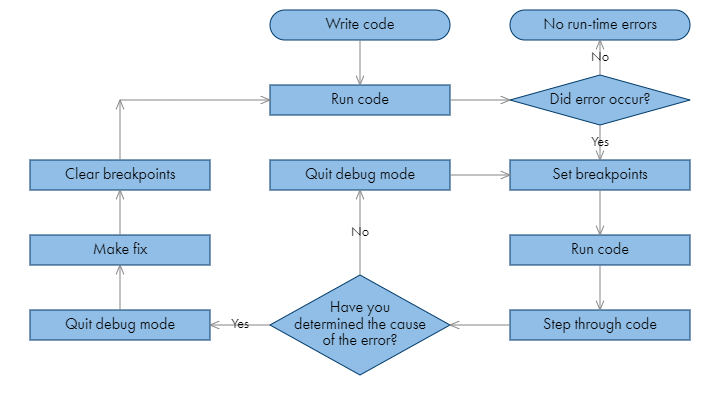

- **Breakpoint**: used to pause the execution of the program at runtime.

- Step, Step In, Step Out

- Continue

Put in breakpoint:

- command `dbstop` with the line number; then use `dbcont`, `dbstep`, `dbquit`

- interactively

**Demo**: lec6_supp`.m`

dbstop in lec6_supp at 3
dbclear in lec6_supp

#### Error handling using `try/catch`

`try`

   `statements`

`catch ``exception`

   `statements`

`end`

A = [1,2;3,4];
B = [1,2];
try
   C = A*B;
   disp("finish multiplication")
catch ME
   disp(ME.message)
   if (strcmp(ME.identifier,'MATLAB:innerdim'))
       msg = ['Matrix multiplication dimension mismatch: A is (', ...
            num2str(size(A)),') while B is (', ...
            num2str(size(B)),').'];
        disp(msg)
   end
%    rethrow(ME)
end 

## Profiler 

Debug and optimize MATLAB code by tracking execution time

- Itemized timing of individual functions

- Itemized timing of individual lines within each function

- Records information about execution time, number of function calls, function dependencies. *The profiler report does not provide information on each individual call to a function, but rather information on the conglomeration of all calls to a function.*

- Useful debugging tool, understand unfamiliar file: *finding bottlenecks*.

`profile (on, off, viewer, clear, -timer)`

`profsave`: save profile report to HTML format

**Demo**: `profiler_ex.m`

Other performance assessment functions:

- `tic, toc, timeit, bench, cputime`

- `memory`

`tic` and `toc`:

- `tic` starts the stopwatch and and `toc` stops it. They are affected by background processes running on the computer.

- Can run multiple times and average the results.

tic
x = rand(1000);
toc

#### Quiz.

Consider two functions:

`function y = trimultiply_1(A,b) y = A*A*A*b; end `

`function y = trimultiply_2(A,b) y = A*(A*(A*b)); end`

Set up the profiler to see if there is any significant difference in time performance from these two functions.

Use `A = rand(1000)` and `b = rand(1000,1)`.

## Benchmark

measure the execution time of six different [benchmarking tasks](https://www.mathworks.com/help/matlab/ref/bench.html#mw_7530574e-c1ce-4258-9a05-5b96d07270e0) on your computer and compares the results to several benchmark computers

bench

clear; clc

## Code Performance

#### Optimize the algorithm itself 

#### Be careful with matrices! 

- Sparse vs. full 

- Parentheses: `A*B*C*v` vs. `A*(B*(C*v)) `

#### Ordering

- Fortran ordering or arrays; Operators with equal precedence evaluated left to right 

#### Vectorization 

- MATLAB highly optimized for array operations 

- Whenever possible, loops should be re-written using arrays 

tic();
i = 0;
for t = 0:.01:10
    i = i + 1;
    y(i) = sin(t);
end
toc()

tic();
y = sin(0:.01:10);
toc()

**Implicit Expansion**

A = [1,2,3;4,5,6]
A + 2
A + [1,2,3]
A + [8;9]

MATLAB will expand an array along any *dimension of length 1* to make it match the size of the other array.

Be cautious about unexpected expansion!

[1,2,3].*[4;5;6]

#### Memory management 

**Data Types with Fixed Memory Requirement**

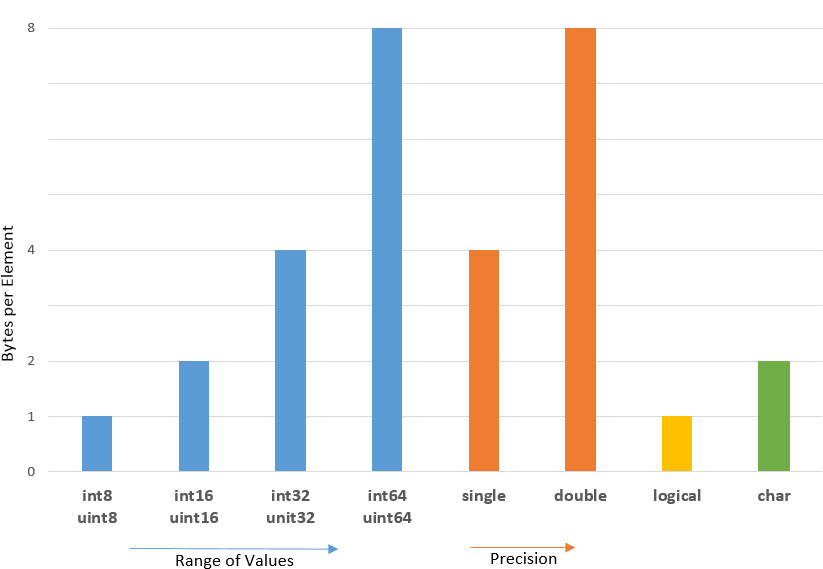

**Container Data Types**

Container variables (tables, cell arrays, and structure arrays) require overhead in addition to the data they store. This *additional memory* is used to store information about the contents of the variable. The amount of the overhead depends on the size of the variable.

- Each cell of a cell array requires memory overhead.

- A table requires minimal overhead for each variable and for storing table properties.

- A structure requires 64 bytes of overhead for each field name and 112 bytes for each container. If a structure array has more than one element, each element will require additional overhead. So the total memory used is *112*(number of elements)*(number of fields) + 64*(number of fields) + data*

x = [1,2,3,4]
w = whos('x')
w.bytes

**Preallocation of arrays**

- Data structures stored as contiguous blocks of data should be preallocated instead of incrementally grown (i.e. in a loop) 

- Each size increment of such a data type requires: location of new contiguous block of memory able to store new object; copying original object to new memory location; writing new data to new memory location

**Delayed copy **

- When a MATLAB array is passed to a function, it is only copied to local workspace when it is modified; i.e. *copy-on-write, *or* lazy-copying*

- Otherwise, entries are accessed based on original location in memory (see supplementary script)

**Contiguous memory **

- Indexing column-wise is much faster than indexing row-wise. MATLAB uses **column-major** memory storage of arrays;

- Numeric arrays are always stored in a contiguous block of memory; 

- Cell arrays and structure arrays are not necessarily stored contiguously. The contents of a given cell or structure are stored contiguously. 

mat = ones(1000, 1000); n = 1e6;

tic();
for i=1:n, vec = mat(1,:); end
toc()
tic();
for i=1:n, vec = mat(:,1); end
toc()

### Memory Management Functions

`clear`: remove items from workspace 

`pack`: consolidate workspace memory 

- frees up needed space by reorganizing information so that it only uses the minimum memory required. All variables from your base and global workspaces are preserved. Any persistent variables that are defined at the time are set to their default value (the empty matrix, []).

- Useful if you have a large numeric array that you know you have enough memory to store, but can’t find enough contiguous memory 

- Not useful if your array is too large to fit in memory

`save`: save workspace variables to file 

`load`: load variables from file into workspace 

`inmem`: Names of funcs, MEX-files, classes in memory 

`memory`: display memory information 

`whos`: list variables in workspace, sizes and types

## Parallel Processing 

### [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html)

Perform parallel computations on multicore computers, GPUs, and clusters.

Tutorials: [Get Started with Parallel Computing Toolbox](https://www.mathworks.com/help/parallel-computing/getting-started-with-parallel-computing-toolbox.html)

To take advantage of this functionality on your desktop, need [Parallel Computing Toolbox](https://uk.mathworks.com/products/parallel-computing.html).

To use Parallel Computing Toolbox functionality in MATLAB Online, need access to a [Cloud Center cluster](https://www.mathworks.com/help/parallel-computing/discover-clusters-and-use-cluster-profiles.html#mw_d47a7dfb-801d-461c-b038-1f5cacf293fa).

Also check [MATLAB Distributed Computing Server](http://www.mathworks.com/products/distriben/) for cluster installation.

**The main reasons to consider parallel computing **

- Save time by distributing tasks and executing these simultaneously

- Solve big data problems by distributing data

- Take advantage of your desktop computer resources and scale up to clusters and cloud computing

**Some useful Parallel Computing concepts**

- *Node:* standalone computer, containing one or more CPUs / GPUs. Nodes are networked to form a cluster or supercomputer

- *Thread:* smallest set of instructions that can be managed independently by a scheduler. On a GPU, multiprocessor or multicore system, multiple threads can be executed simultaneously (multi-threading)

- *Batch*: off-load execution of a functional script to run in the background

- *Scalability*: increase in parallel speedup with the addition of more resources

**Parallel Computing Toolbox allows you to**

- Accelerate your code using interactive parallel computing tools, such as `parfor` and `parfeval`

- Scale up your computation using interactive Big Data processing tools, such as `distributed`, `tall`, `datastore`, and `mapreduce`

- Use `gpuArray` to speed up your calculation on the GPU of your computer

- Use `batch` to offload your calculation to computer clusters or cloud computing facilities

#### Installation of toolbox

- Select the checkbox during the initial installation of MATLAB

- Add-Ons $\to$ Get Add-Ons $\to$ search for the MathWorks toolbox $\to$ install

To view the list of all the toolboxes installed, use

ver

To check the number of cores:

feature('numcores')

#### Example 

tic
n = 200;
A = 1000;
a = zeros(n);
for i = 1:n
    a(i) = max(abs(eig(rand(A))));
end
toc

With parallel  computing - use of `parfor`:

A parfor-loop in MATLAB executes a series of statements in the loop body in parallel.

tic
n = 200;
A = 1000;
a = zeros(n);
parfor i = 1:n
    a(i) = max(abs(eig(rand(A))));
end
toc

Use of `parpool` (need to create a cluster)

parpool

[More tutorials on this.](https://www.mathworks.com/help/parallel-computing/parpool.html)

*Reference: MathWorks Help Center Documentation*